# Stair

% for j = 37%:length(stair_metastruct)
    
%     P = stair_metastruct(j).P;
    total_trial_dur = P(1).ON_dur+2*P(1).OFF_dur;
    time = linspace(0,total_trial_dur,P(1).single_trial_length);
    
    stimulus = -P.mean_movement;
    mid_point = length(stimulus)/2;
    % x = [5 9.5 14.5 19.5 24.5 29.5 34.5 39.5 44.5 49.5 54.5 59.5 64.5 69.5 74.5 79.5 84.5; ...
    %     5.5 10.5 15.5 20.5 25.5 30.5 35.5 40.5 45.5 50.5 55.5 60.5 65.5 70.5 75.5 80.5 85; ...
    %     5.5 10.5 15.5 20.5 25.5 30.5 35.5 40.5 45.5 50.5 55.5 60.5 65.5 70.5 75.5 80.5 85; ...
    %     5 9.5 14.5 19.5 24.5 29.5 34.5 39.5 44.5 49.5 54.5 59.5 64.5 69.5 74.5 79.5 84.5];
    
    %     intendedStimulus = nwb_in.stimulus_presentation.get('mechanical_stimulus');
        intendedStimulus = stim.data.load;
        S = abs(diff(intendedStimulus(:,1)));
%     S = abs(diff(P.intendedStim));
    
    x = [];
    for i=1:length(S)-1
        if (S(i)==0 && S(i+1)>0) || (S(i)>0 && S(i+1)==0)
            x = [x i];
        end
    end
    x = reshape(x,2,[]);
    x(3,:) = x(2,:);
    x(4,:) = x(1,:);
    x = x/P.fs;
    
    y_stim = repmat([-1 -1 1 1]', 1, 16);
    y_gcfr = repmat([0 0 150 150]', 1,16);
    
    figure;
    % for i=7:4:54
    %     i
    ax1 = subplot(2,1,1); plot(time, stimulus, 'k'); hold on;
    patch(x,y_stim,[0.8500 0.3250 0.0980], 'FaceAlpha' , 0.3, 'EdgeColor', 'none');
    ylabel('Antennal position (deg)', 'FontSize',12);
    title(join([num2str(j) replace([P(1).date P(1).filename], '_','-')], '   '));
    %     for i=7:5:54
    %         i
    %         fill([time(i*fs+1),time(i*fs+1), time((i+1)*fs), time((i+1)*fs)], [-0.88 -0.86 -0.86 -0.88], 'r', 'FaceAlpha',0.1);
    %     end
    
    ax2 = subplot(2,1,2);
    %     plot(time(1:single_trial_length), P.avg_gcfr, 'k'); hold on;
    [lineOut, ~] = stdshade(P.gcfr,0.2,'k',time); %10 = (fs/L)*gcfr Hz
    lineOut.LineWidth  = 0.05;
    patch(x,y_gcfr, [0.8500 0.3250 0.0980], 'FaceAlpha' , 0.3, 'EdgeColor', 'none');
    %     for i=7:5:54
    %         fill([time(i*fs+1),time(i*fs+1), time((i+1)*fs), time((i+1)*fs)], [0 100 100 0], 'r', 'FaceAlpha',0.1);
    %     end
    ylabel('Avg. GCFR (Hz)','FontSize',12);
    xlabel('Time (s)','FontSize',12);
    
    xlim([0 90]);
    linkaxes([ax1 ax2], 'x');
    
    
    figure;
    
    ax1 = subplot(2,1,1); plot(time(1:P.single_trial_length/2), stimulus(1:mid_point)); hold on;
    plot(time(1:P.single_trial_length/2), fliplr(stimulus(mid_point+1:end)));
    ylabel('Antennal position (deg)', 'FontSize',12);
    title(join([num2str(j) replace([P(1).date P(1).filename], '_','-')], '   '));
    
    ax2 = subplot(2,1,2); plot(time(1:P.single_trial_length/2), P.avg_gcfr(1:mid_point)); hold on;
    plot(time(1:P.single_trial_length/2), fliplr(P.avg_gcfr(mid_point+1:end)));
    ylabel('Avg. GCFR (Hz)',"FontSize",12);
    xlabel('Time (s)',"FontSize",12);
    
    %     xlim([0 23]);
    linkaxes([ax1 ax2], 'x');
    
% end

## Ramp

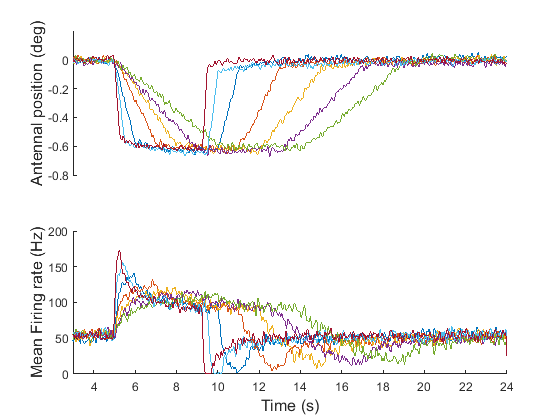

% for j = 1:8 %length(ramp_metastruct)
%     P = ramp_metastruct(j).P;
total_trial_dur = P(1).ON_dur+2*P(1).OFF_dur;
time = linspace(0,total_trial_dur,P(1).single_trial_length);

figure;

for i=1:length(P)
    
    ax1 = subplot(2,1,1); plot(time, -P(i).mean_movement); hold on;
    %     lgd = legend(["1 s", "2 s","0.5 s", "0.5 s"],"Location","northeast","NumColumns",1);
    %     title(lgd, "Ramp duration");
    ylabel('Antennal position (deg)', 'FontSize',12);
%     title(replace([P(1).date P(1).filename], '_','-'));
    ax1.Box = 'off';
    ax1.XAxis.Visible = 'off';
    
    ax2 = subplot(2,1,2); plot(time, P(i).avg_gcfr); hold on;
    ylabel('Mean Firing rate (Hz)', 'FontSize',12);
    xlabel('Time (s)', 'FontSize',12);
    ax2.Box = 'off';
    
    linkaxes([ax1 ax2], 'x');
    xlim([3 Inf]);
    
end

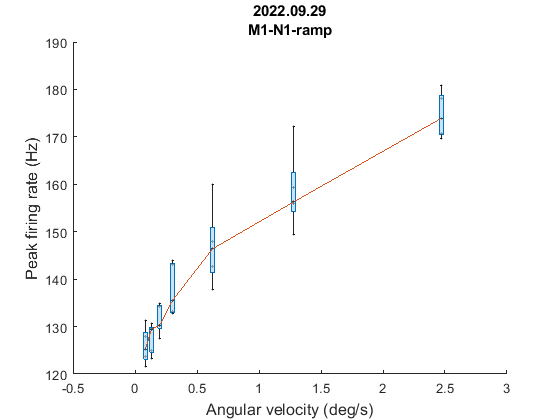



%FR Vs Velocity
% figure;
max_FR = [];
velocity = [];
max_FR_sorted = [];
velocity_sorted = [];
% raster = P.raster(start_stim:stop_stim);
auc = zeros(1,length(P));
nSpikes = zeros(1,length(P));
avg_spikes = [];

for i=1:length(P)
    start_point = P(i).OFF_dur*fs;
    stim_end_point = (P(i).OFF_dur+P(i).ON_dur)*fs;
    stim_name = split(P(i).stim_name);
    delta_t = str2double(stim_name(2));
    baselineFR = mean(P(i).avg_gcfr(1:3*fs),"all");
    pos_ref = mean(-P(i).mean_movement(1:3*P(1).fs));
    pos_stim = mean(-P(i).mean_movement(8*P(1).fs:9*P(1).fs));
    amplitude = abs(pos_ref - pos_stim);
    velocity_values = repmat((amplitude/delta_t), [P(i).complete_trials,1]);
    velocity = [velocity; velocity_values];
    spikes = sum(P(i).raster(:,start_point:start_point+delta_t*fs),2)./delta_t;
    %         velocity = [velocity; velocity];
    %         [min_val,stop_point] = min(P(i).avg_gcfr(start_point:(P(i).ON_dur+P(i).OFF_dur)*fs));
%     for timestamps = start_point : stim_end_point
%         if P(i).avg_gcfr(timestamps)> baselineFR && P(i).avg_gcfr(timestamps+1)<= baselineFR
%             stop_point = timestamps
%             break;
%         end
%     end
%     figure; plot(time,P(i).avg_gcfr); hold on;
%     xline(stop_point/fs, 'r');
%     xline(start_point/fs, 'g');
%     yline(baselineFR);
%     ylabel('Mean firing rate (Hz)');
%     xlabel('Time (s)');
%     auc(i) = trapz(P(i).avg_gcfr(start_point:start_point+stop_point))/stop_point;
%     nSpikes(i) = mean(sum(P(i).raster(start_point:start_point+stop_point),2))*fs/stop_point;
    
    max_FR = [max_FR; max(P(i).gcfr, [], 2)];
    avg_spikes = [avg_spikes; spikes];
    
end

[velocity_sorted, idx] = sort(velocity, 'ascend');
max_FR_sorted = max_FR(idx);
avg_spikes_sorted = avg_spikes(idx);
meanMaxFR = median(reshape(max_FR_sorted, P(i).complete_trials, []),1);
meanSpikes = mean(reshape(avg_spikes_sorted, P(i).complete_trials, []),1);

vel = unique(velocity_sorted);
[vel_sorted,idx] = sort(unique(velocity), 'ascend');
auc = auc(idx);
nSpikes = nSpikes(idx);

% velocity_sorted = num2str(velocity_sorted, '%.3f');
figure;
boxchart(velocity_sorted, max_FR_sorted, 'BoxWidth', 0.03, 'MarkerStyle',"+"); hold on;
plot(vel, meanMaxFR);  hold on;
scatter(velocity_sorted, max_FR_sorted, 5,'k','filled','MarkerFaceAlpha',0.3);
% boxplot(max_FR_sorted, velocity_sorted);
% ylim([0 100]);
ylabel('Peak firing rate (Hz)', 'FontSize',12);
xlabel('Angular velocity (deg/s)', 'FontSize',12);
title(replace([P(1).date P(1).filename], '_','-'));


FR =reshape(max_FR_sorted, P(i).complete_trials, []);
p = ranksum(FR(:,1), FR(:,end))

p = 0.0079


% figure;
% plot(vel_sorted, nSpikes, 'ro-');
% ylabel('Normalised number of spikes during phasic firing');
% xlabel('Angular velocity (deg/s)');
% title(replace([P(1).date P(1).filename], '_','-'));
% end

% figure;
% boxchart(velocity_sorted, avg_spikes_sorted, 'BoxWidth', 0.03, 'MarkerStyle',"+"); hold on;
% % plot(vel, meanSpikes, '-o');  hold on;
% semilogx(vel, meanSpikes, '-o');  hold on;
% scatter(velocity_sorted, avg_spikes_sorted, 10,'k','filled', 'MarkerFaceAlpha',0.5);
% ylabel('Mean firing rate (Hz)', 'FontSize',12);
% xlabel('Angular velocity (deg/s)', 'FontSize',12);
% title(replace([P(1).date P(1).filename], '_','-'));

% end

## Step

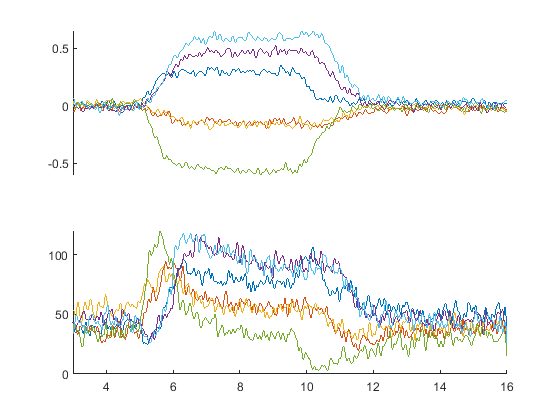

% for j = 3%:length(step_metastruct)
%     P = step_metastruct(j).P;
total_trial_dur = P(1).ON_dur+2*P(1).OFF_dur;
time = linspace(0,total_trial_dur,P(1).single_trial_length);

figure;
for i=1:length(P)
    
    ax1 = subplot(2,1,1); plot(time, -P(i).mean_movement); hold on;
    %     lgd = legend(["0.005 mm", "0.01 mm","-0.005 mm","-0.01 mm"],"Location","northeast","NumColumns",1);
    %     title(lgd, "Step amplitude");
%     ylabel('Antennal position (deg)', 'FontSize',12);
%     title(replace([P(1).date P(1).filename], '_','-'));
ax1.Box = 'off';
    ax1.XAxis.Visible = 'off';
    
    
    ax2 = subplot(2,1,2); plot(time, P(i).avg_gcfr); hold on;
%     ylabel('Mean Firing rate (Hz)', 'FontSize',12);
%     xlabel('Time (s)', 'FontSize',12);
    ax2.Box = 'off';
    
    linkaxes([ax1 ax2], 'x');
    xlim([3 Inf])
    
end


%Steady state firing rate Vs Position

figure;
steadystateFR = [];
position = [];
% FRsorted = [];
% position_sorted = [];
meanFR = [];
ssLoc = P(1).OFF_dur+3;

for i=1:length(P)
    stim_name = split(P(i).stim_name);
    delta_t = str2double(stim_name(2));
    pos_ref = mean(mean(P(i).antennal_movement(:,1:3*P(1).fs),2));
    pos_stim = mean(mean(P(i).antennal_movement(:, ssLoc*P(1).fs:(ssLoc+1)*P(1).fs),2));
    amplitude = pos_ref - pos_stim;
    position_values = repmat(amplitude, [P(i).complete_trials,1]);
    position = [position; position_values];
    
    steadystateFR = [steadystateFR; mean(P(i).gcfr(:,ssLoc*P(1).fs:(ssLoc+1)*P(1).fs),2)];
    
    
end

[position_sorted, idx] = sort(position, 'ascend');
FRsorted = steadystateFR(idx);
meanFR = median(reshape(FRsorted, P(i).complete_trials, []),1);

Error using reshape
Product of known dimensions, 4, not divisible into total number of elements, 27.

pos = unique(position_sorted);
% plot(pos, meanFR, '-o'); hold on;
% position_sorted = num2str(position_sorted, '%.3f');
boxchart(position_sorted, FRsorted, 'BoxWidth', 0.1, 'MarkerStyle','+'); hold on;
title(replace([P(1).date P(1).filename], '_','-'));
% boxplot(FRsorted, position_sorted);
ylabel('Firing rate (Hz)');
xlabel('Position (deg)');

FR =reshape(FRsorted, P(i).complete_trials, []);
if length(P) == 4
    plot(pos(1:2),median(meanFR(:,1:2),1), '-ro');
    plot(pos(3:4),median(meanFR(:,3:4),1), '-ro');
    scatter(position_sorted, FRsorted, 10,'k','filled','MarkerFaceAlpha',0.5);
    p1 = ranksum(FR(:,1), FR(:,2));
    p2 = ranksum(FR(:,3), FR(:,4));
else
    plot(pos(1:3),median(meanFR(:,1:3),1), '-ro');
    plot(pos(4:6),median(meanFR(:,4:6),1), '-ro');
    p1 = ranksum(FR(:,1), FR(:,3));
    p2 = ranksum(FR(:,4), FR(:,6));
end
text(-1,10,sprintf('%0.3f',p1));
text(0.5,10,sprintf('%0.3f',p2));
%
ylim([0 inf]);

% end